サンプル数25の結果で混合屈折度と信号ズレとの関係をプロットする．

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
load('transducer_2board')

r_num = t_num/2;
diff_point_each = zeros(r_num, length(aveSOS));
for ii = 1:length(aveSOS)
    [Min ,ind] = min(tof_cell(101:200,:,ii),[],1);
    for jj = 1:length(diff_point_each)
        diff_point_each(jj,ii) = (ind(1,jj) - jj);
    end
end

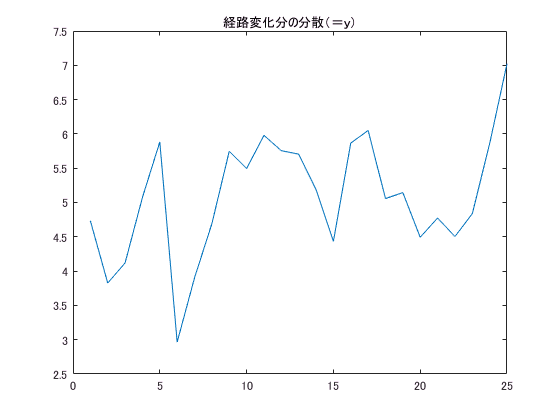

w = 1;
y = std(diff_point_each,w,1);
figure;
plot(y);
title('経路変化分の分散（＝ｙ）')

std_diff_point = y;
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion');
save('std_diff_point.mat','std_diff_point');

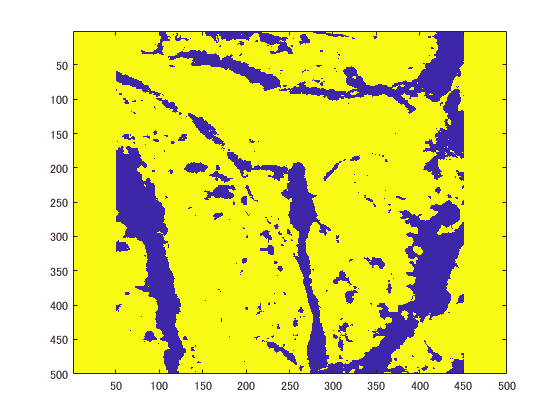

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter');
load('case1')
figure;
imagesc(medium.sound_speed);

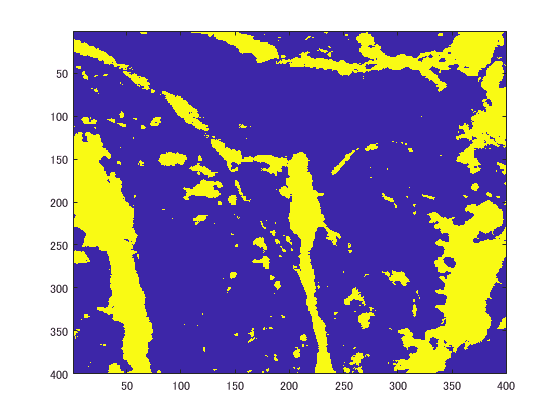

a = medium.sound_speed(51:450,51:450);
b = (a == min(min(a)));
imagesc(b);

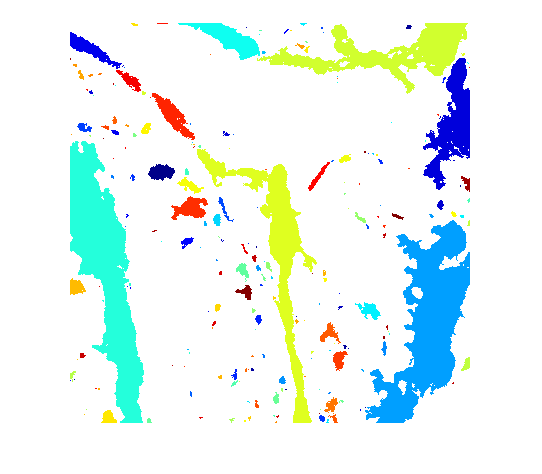

lbl = bwlabel(b);
nLabels = max(lbl(:));
rgb = label2rgb(lbl, jet(nLabels), 'w', 'shuffle');
imshow(rgb);

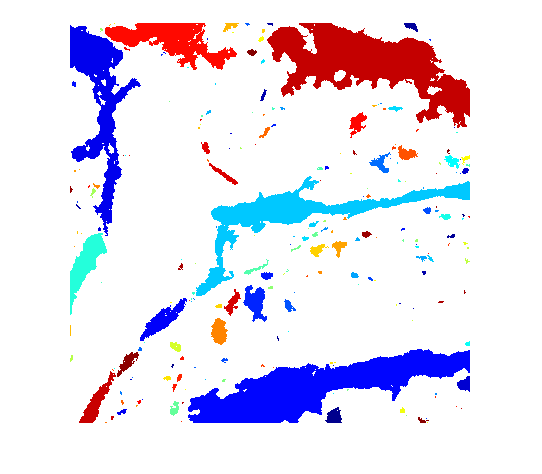

B = imrotate(b,90);
lbl = bwlabel(B);
nLabels = max(lbl(:));
rgb = label2rgb(lbl, jet(nLabels), 'w', 'shuffle');
imshow(rgb);

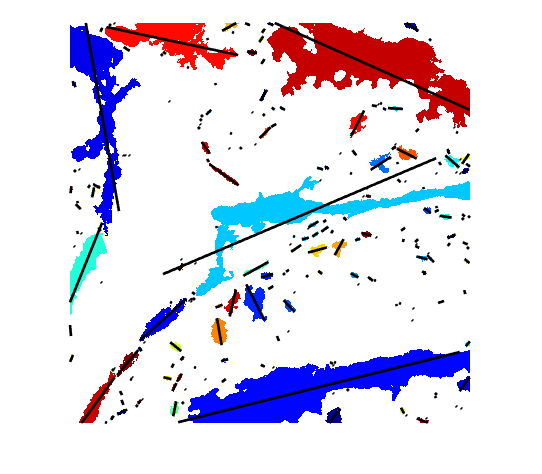

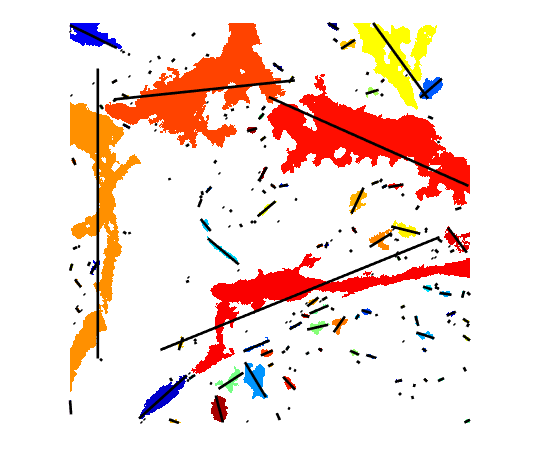

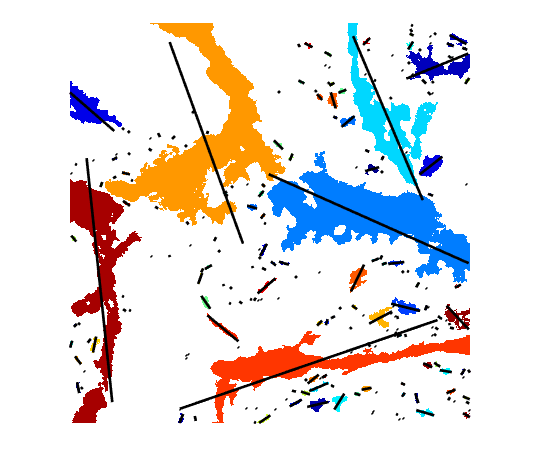

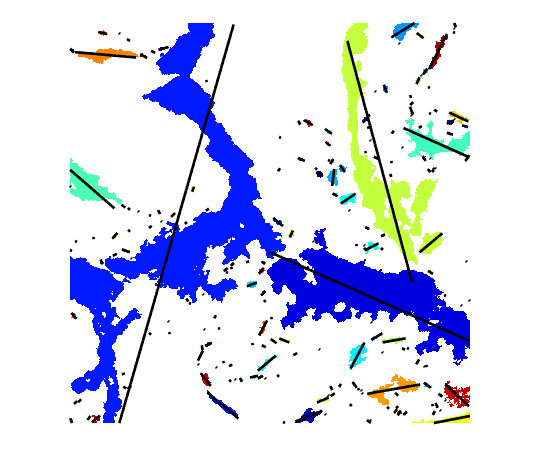

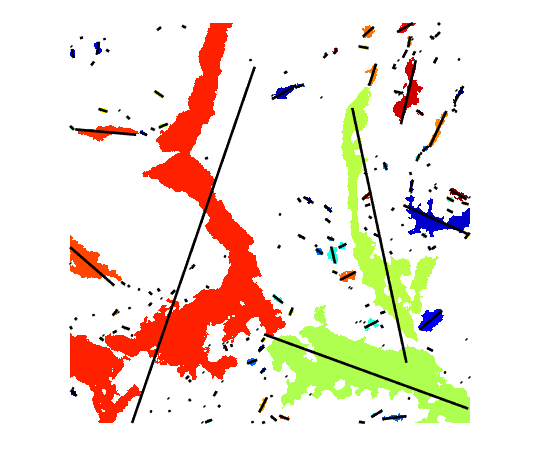

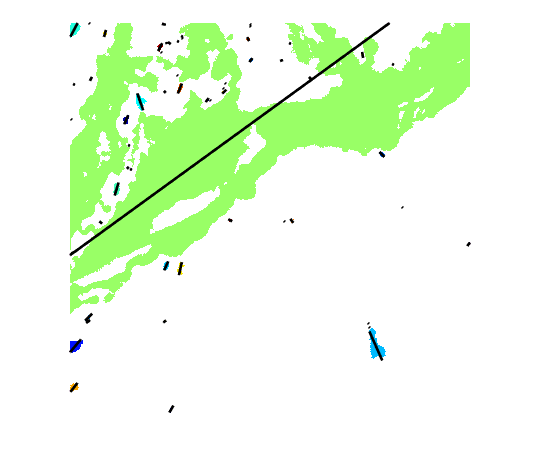

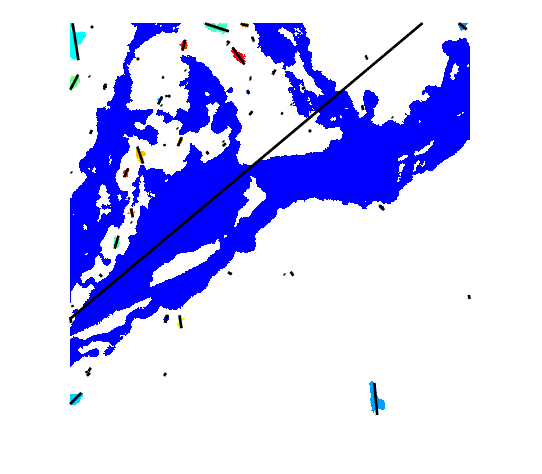

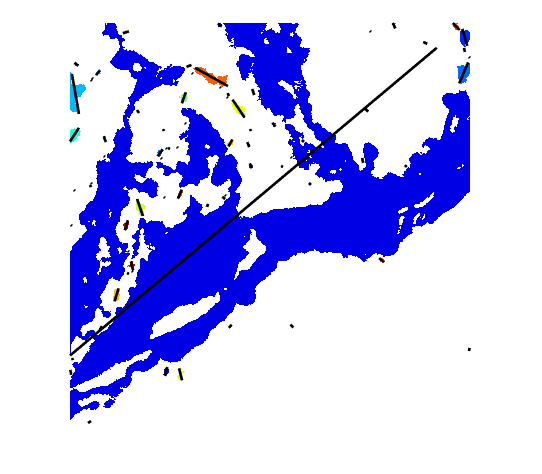

refractive_dispersion = zeros(1,25);
native_refractive_dispersion = zeros(1,25);
for ii = 1:25
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\medium\2018_08_10_realisticScatter');
    
    myfilename = sprintf('case%d',ii);
    load(myfilename,'medium')
    tmp = medium.sound_speed(51:450,51:450);
    tmp2binalize = (tmp == min(min(tmp)));
    tmp2binalize = imrotate(tmp2binalize,90);
    lbl = bwlabel(tmp2binalize);
    nLabels = max(lbl(:));
    rgb = label2rgb(lbl, jet(nLabels), 'w', 'shuffle');
    [diams, thetas] = imMaxFeretDiameter(lbl);
    centros = imCentroid(lbl);
    cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion');
    figure;
    imshow(rgb);
    hold on
    drawCenteredEdge([centros diams thetas], 'linewidth', 2, 'color', 'k');
    hold off
    savefilename = sprintf('case%d_ferret',ii);
    saveas(gcf,savefilename,'fig');
    saveas(gcf,savefilename,'png');
    fig2=figure(30);
    subplot(5,5,ii);
    imshow(rgb);
    hold on
    drawCenteredEdge([centros diams thetas], 'linewidth', 2, 'color', 'k');
    hold off
    thetas_rad = deg2rad(thetas);
%     total_diams = sum(diams);
    [max_diam, ind_max] = max(diams);
    refractive_dispersion(1,ii) = sin(thetas_rad(ind_max,1)-pi/2);
    native_refractive_dispersion(1,ii) = thetas_rad(ind_max,1);
end

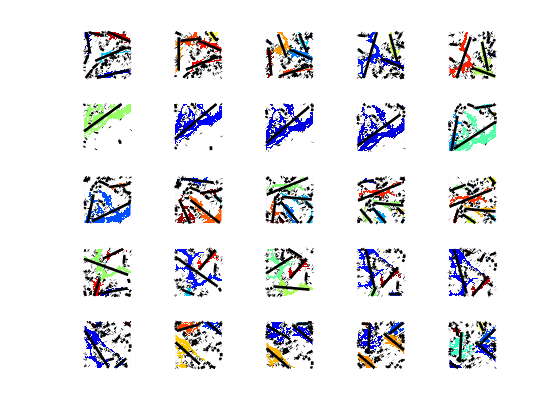

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion');
save('refractive_dispersion2.mat','refractive_dispersion','native_refractive_dispersion');
saveas(fig2,'ferret_all','fig');
saveas(fig2,'ferret_all','png')

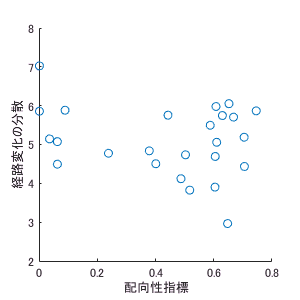

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion');
load refractive_dispersion.mat
load std_diff_point.mat
figure;
scatter(abs(refractive_dispersion),std_diff_point);
ylabel('経路変化の分散')
xlabel('配向性指標')
axis square
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion\displace_vs_direction2','png',[300,300])

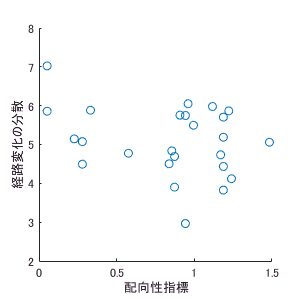

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion');
load refractive_dispersion2.mat
load std_diff_point.mat
figure;
scatter(abs(native_refractive_dispersion-pi/2),std_diff_point);
ylabel('経路変化の分散')
xlabel('配向性指標')
axis square
exportfig('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_31_structure_dispersion\displace_vs_direction3','png',[300,300])